#### ** Here we see the filter bank as designed by** ***C. Li, C. Zheng, and C. Tai, “Detection of ECG characteristic points using wavelet transforms,” IEEE Trans. Biomed. Eng., vol. 42, pp. 21–28, Jan. 1995"***

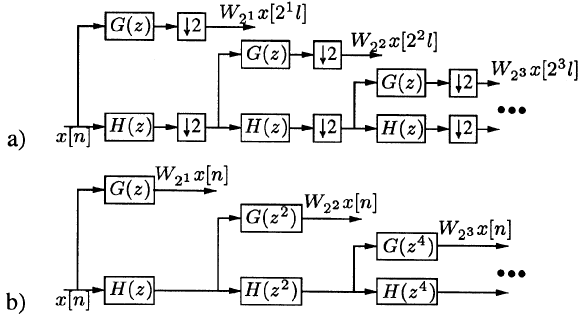

Two filter-bank implementations: a) Mallat's algorithm  b) Algorithm a trous.

Ofcourse we will utilize algorithm a trous.

We will operate on qtdb database sampled at 250Hz

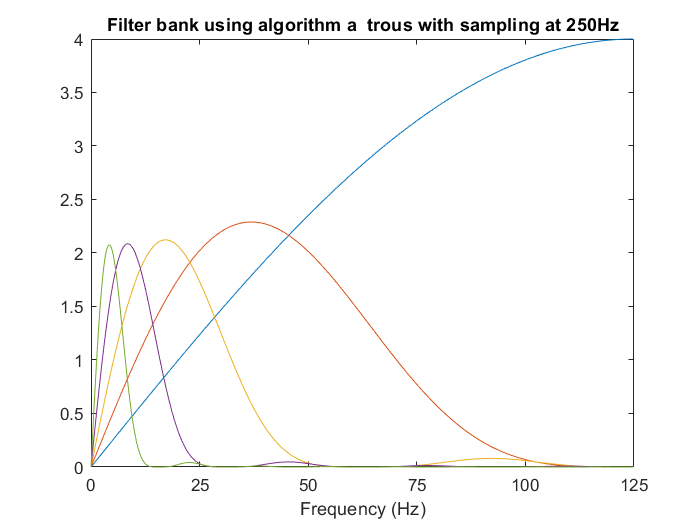

fs = 250;
Gz = 2*[1 -1];
Hz = 1/8*[1 3 3 1];
level = 5;
G = {};
H = {};
G{1} = [Gz];
H{1} = [Hz];
for i = 1:level
    G{i+1} = upsample(Gz,2^i) ;
    H{i+1} = upsample(Hz,2^i) ; 
end

W{1} = G{1};
for i = 2:level
    temp = G{i};
    for j = 1:(i-1)
        temp = conv(temp , H{j});
    end
    W{i} = [temp];
end

for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]);
    q = q*125/pi;
    plot(q,abs(h));
    hold on
end
title 'Filter bank using algorithm a  trous with sampling at 250Hz'
xlabel 'Frequency (Hz)'
xlim([0,125])
xticks([0,25,50,75,100,125])

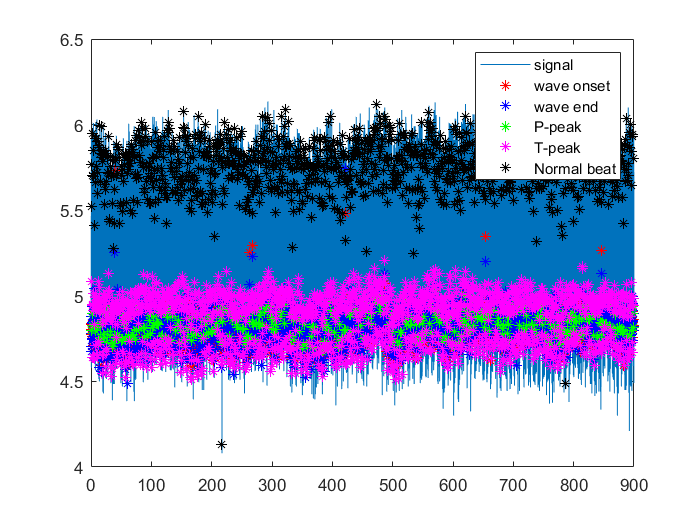

load('sig_qtdb.mat')
load('tm_qtdb.mat')
load('record_qtdb.mat')
load('a_qtdb.mat')
figure
plot(tm,sig,tm(record(find(a=='('))),sig(record(find(a=='('))),'r*');
hold on
plot(tm(record(find(a==')'))),sig(record(find(a==')'))),'b*');
plot(tm(record(find(a=='p'))),sig(record(find(a=='p'))),'g*');
plot(tm(record(find(a=='t'))),sig(record(find(a=='t'))),'m*');
plot(tm(record(find(a=='N'))),sig(record(find(a=='N'))),'k*');
legend('signal','wave onset','wave end','P-peak','T-peak','Normal beat')

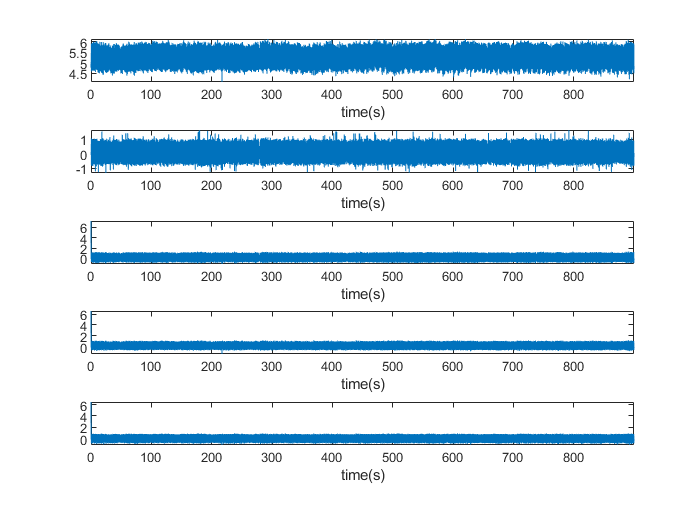

record=record(find(a=='N'));
x=sig;
% x=sig(1:1000);
% tm=tm(1:1000);

figure
w1=conv([0;x],W{1},'same');
w1(end)=[];
w1(1)=[];
w1=[w1;0];
w2=conv([0;0;0;0;x],W{2},'same');
w2(end-3:end)=[];
w2(1:3)=[];
w2=[w2;zeros(3,1)];
w3=conv([0;0;0;0;0;0;0;0;0;0;x],W{3},'same');
w3(end-9:end)=[];
w3(1:7)=[];
w3=[w3; zeros(7,1)];
w4=conv([zeros(22,1);x],W{4},'same');
w4(end-21:end)=[];
w4(1:15)=[];
w4=[w4;zeros(15,1)];
w5=conv(x,W{5},'same');
figure()
subplot(5,1,1)
plot(tm,x)
axis tight
xlabel 'time(s)'
subplot(5,1,2)
plot(tm,w1)
xlabel 'time(s)'
axis tight
subplot(5,1,3)
plot(tm,w2)
xlabel 'time(s)'
axis tight
subplot(5,1,4)
plot(tm,w3)
axis tight
xlabel 'time(s)'
subplot(5,1,5)
plot(tm,w4)
axis tight
xlabel 'time(s)'

Now we move to peak detection

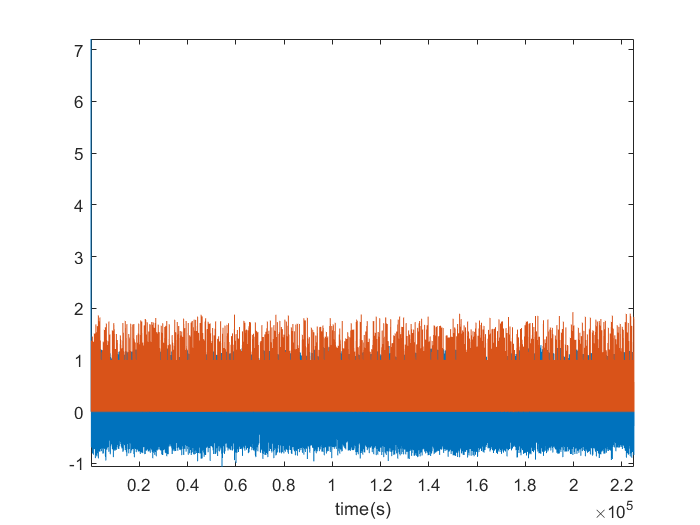

e_1_QRS=rms(w1);
e_2_QRS=rms(w2);
e_3_QRS=rms(w3);
e_4=0.5*rms(w4);
peaks=w2.*(abs(w2)>e_2_QRS);
temp1=[0;peaks];
temp1(end)=[];
temp2=[peaks;0];
temp2(1)=[];
figure
plot(peaks)
axis tight
peaks=peaks.*((temp2.*temp1)<0)+((temp2.*temp1)<0);
hold on
plot(peaks)
axis tight
xlabel 'time(s)'

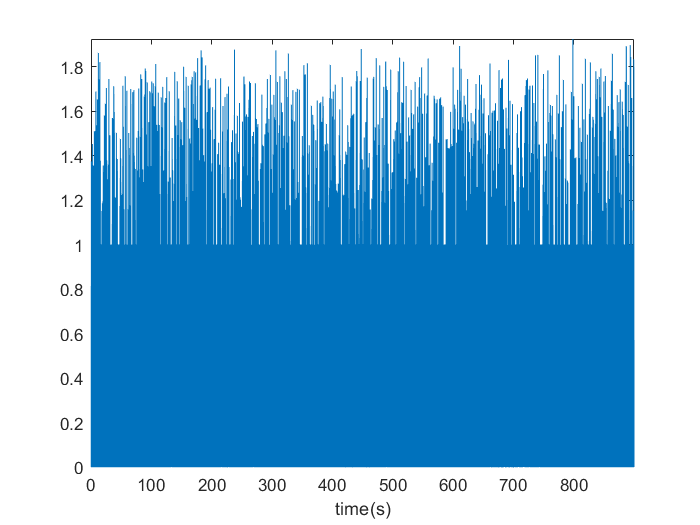

% peaks=w3.*(abs(w3)>e_3_QRS);
% temp1=[0;peaks];
% temp1(end)=[];
% temp2=[peaks;0];
% temp2(1)=[];
% figure
% plot(peaks)
% axis tight
% peaks=peaks.*((temp2.*temp1)<0);
% hold on
% plot(peaks)
% axis tight
% xlabel 'time(s)'
e_T=0.25*rms(w4);
e_P=0.02*rms(w4);
% peaks=w4.*(abs(w4)>e_T);
figure
plot(tm,peaks)
axis tight
xlabel 'time(s)'

% To find redundant positive detections
for i = 1:size(peaks,1)-4
    if(peaks(i)~=0)
        if(peaks(i+1)~=0)
            peaks(i)=0;
        elseif(peaks(i+2)~=0)
            peaks(i)=0;
        elseif(peaks(i+3)~=0)
            peaks(i)=0;
        elseif(peaks(i+4)~=0)
            peaks(i)=0;
        end
    end
end
% To find redundant false detections
k=find(peaks>0);
separation=[0;diff(k)];

% count=0;
% last_i=0;
% for i=1:size(peaks,1)-1
%     if(peaks(i)~=0)
%         count=count+1;
%         if(last_i-i)<
%     end
%     
k=find(peaks>0);
positive=0;
for i = 1:size(record,1)
    if(min(abs(record(i)-k))<3)
        positive=positive+1;
    end
end

fprintf('success is %d', positive/size(record,1)*100)

success is 9.659614e+01

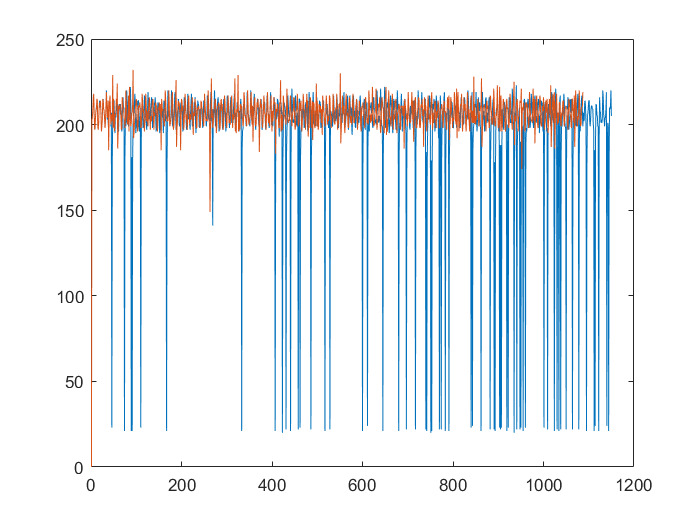

%To find false negatives
plot(separation)
separation=[0;diff(record)];
hold on
plot(separation)

true_positive=0;
false_negative=0;
for i = 1:size(record,1)
    if(min(abs(record(i)-k))<4)
        true_positive=positive+1;
    else
        false_negative=false_negative+1;
    end
end
false_positive=0;
for i = 1:size(k,1)
    if(min(abs(k(i)-record))>3)
        false_positive=false_positive+1;
    end
end
true_positive

true_positive = 1051

false_negative

false_negative = 37

false_positive

false_positive = 100

se=true_positive/(true_positive+false_negative)*100

se = 96.5993

p=true_positive/(true_positive+false_positive)*100

p = 91.3119

QRS_pos=peaks>0;